Generate the transfer functions of the following system:

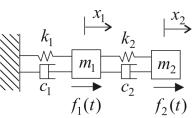

syms s t F1 F2 X1 X2

Set the value for $m_1 ,m_2 ,k_1 ,k_2 ,b_1 ,b_2$. Set the value to zero if there is no such component. Never set mass to zero. You can set $f_1$ or $f_2$ to zero if the corresponding input does not exist. Set $f_1$ to $F_1$ and $f_2$ to $F_2$, if they are arbitrary. It can also be in any function in a Laplace form. See the commented line as an example.

m1 = 1;
m2 = 1;

b1 = 0;
b2 = 0;

k1 = 1;
k2 = 1;

%f1 = F1;
f1 = 0;
%f1 = laplace(sin(2*t), t, s); % This is a sine function
%f1 = 1/s; % This is a unit step function
%f1 = 0;

%f2 = F2;
%f2 = laplace(sin(2*t), t, s); % This is a sine function
f2 = 1/s; % This is a unit step function
%f2 = 0;

M = [m1 0; 0, m2];
B = [b1+b2 -b2; -b2, b2];
K = [k1+k2 -k2; -k2 k2 ];


H = s^2*M+s*B+K;
eqTF = [X1; X2] == simplify(inv(H)*[f1; f2])

$$eqTF = \left(\begin{array}{c} X_{1}=\frac{1}{s^{5}+3\,s^{3}+s}\\ X_{2}=\frac{s^{2}+2}{s\,\left(s^{4}+3\,s^{2}+1\right)} \end{array}\right)$$

Now, we shall plot the system responses in time domain. Principally, we perform partial fraction expansion and inverse Laplace operation to convert the systems into time domain.

We CAN NOT do this if $f_1$ or $f_2$ is arbitrary. 

%  Go to time domain from here
Qs = partfrac(rhs(eqTF), s, 'FactorMode','real');
Qt = ilaplace(Qs, s, t);
Qt = rewrite(Qt, 'sincos');
Qt = vpa(simplify(Qt, 'Steps',10, 'IgnoreAnalyticConstraints',1),4)

$$Qt = \left(\begin{array}{c} 0.1708\,\cos\left(1.618\,t\right)-1.171\,\cos\left(0.618\,t\right)+1.0\\ 2.0-0.1056\,\cos\left(1.618\,t\right)-1.894\,\cos\left(0.618\,t\right) \end{array}\right)$$

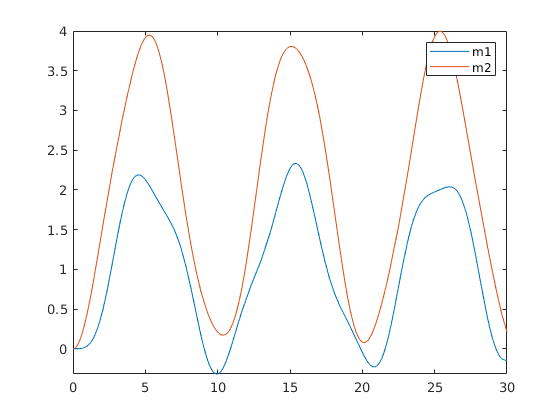

fplot(Qt,[0 30])
legend('m1', 'm2')